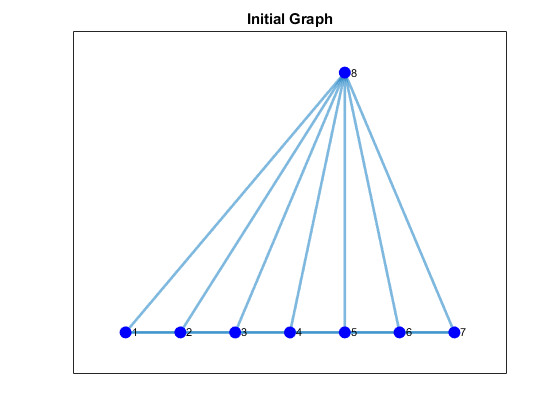

%% Line formation initialization + consensus with polar coordinates

clear 
close all

% initialize UGV struct
ugv.xw = 1;  ugv.yw = 0; ugv.hw = 0;    % robot position and orientation wrt world frame
ugv.xr = 0;  ugv.yr = 0; ugv.hr = 0;    % robot position and orientation wrt its frame

% !!! pose wrt its frame is needed only to have the right arrays and matrices dimension

% initialize AUV struct - line formation
auv.id = [ 1  2  3  4  5  6  7].';      % auv id 
auv.xw = [-3 -2 -1  0  1  2  3].';      % coords in world frame
auv.yw = [-1 -1 -1 -1 -1 -1 -1].';
auv.hw = [ 0  0  0  0  0  0  0].';      % heading angle in world frame

auv.xr = auv.xw - ugv.xw;               % coords in robot frame (UGV)
auv.yr = auv.yw - ugv.yw;               
auv.yr = auv.hw - ugv.hw;               % heading angle in robot frame (UGV)

auv.n  = length(auv.id);                % number of auvs

% !!! heading angles are useless now, but are initialized since can be usefull 
% !!! in the future ... who knows

% build the graph topography: every AUV is connected with the UGV (assumed
% to be the leader for now), and with the two neighbors. Considering the order 
% of the final formation (a circle), seen in anti-clockwise direction looking the center, 
% the left neighbor is the previous (V--), while the right one is the next (V++).

% initilize the nodes
Gx = [auv.xw; ugv.xw];
Gy = [auv.yw; ugv.yw];

% the total number of edges given n auvs are so:
% n + 2n = 3n in case of digrah
% n + n  = 2n in case of graph (we will consider this case for now)

edges = zeros(2*auv.n , 2);

% connection with robot
for i = 1 : auv.n
    edges(i,:) = [i length(auv.id)+1];
end

% connection between auvs
for i = 1 : auv.n - 1
    edges(i+auv.n,:) = [i i+1];
end
% connection of last with first
edges(end, :) = [length(auv.id) 1];

% plot the graph
figure(1); 
G = graph(edges(:,1),edges(:,2));
plot(G,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph')

%% Retrieve auvs position wrt robot frame and transform in polar coords

auv.xr = auv.xw - ugv.xw;
auv.yr = auv.yw - ugv.yw;

auv.rho = sqrt(auv.xr.*auv.xr + auv.yr.*auv.yr);
auv.th  = mod(atan2(auv.yr,auv.xr),2*pi);

% define distance from robot to keep and distance error
auv.d = 1;
auv.d_err = auv.rho - ones(auv.n , 1) * auv.d;

% normalize error to assure having a value < 1
auv.d_err_norm = auv.d_err./auv.rho;

% check
check = table(auv.th *180/pi, auv.rho, auv.d_err, auv.d_err_norm, ...
    'VariableNames', {'theta', 'rho', 'dist err', 'normalized d_err'});
disp(check);

    theta      rho      dist err    normalized d_err
    ______    ______    ________    ________________

    194.04    4.1231     3.1231         0.75746     
    198.43    3.1623     2.1623         0.68377     
    206.57    2.2361     1.2361         0.55279     
       225    1.4142    0.41421         0.29289     
       270         1          0               0     
       315    1.4142    0.41421         0.29289     
    333.43    2.2361     1.2361         0.55279     



% number of iterations
n = 500;

% consensus control parameters
K.rho = 0.1;
K.th  = 0.2;

% generate labels for plot
labels = strings(auv.n + 1,1);
for i = 1 : auv.n
    labels(i) = string(auv.id(i));
end
labels(end) = 'R';

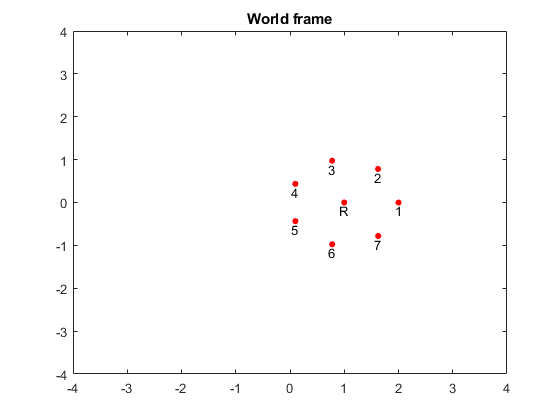

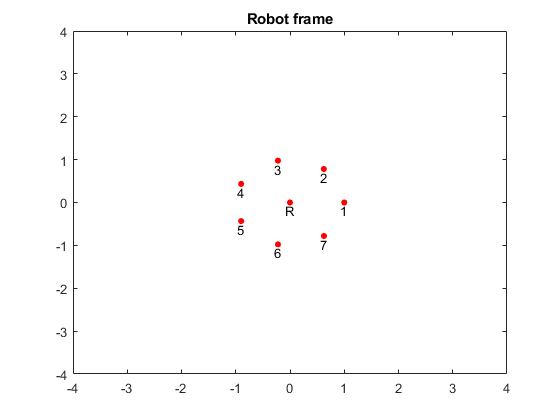


for i=1:n
    
    % Retrieve auvs positions wrt robot frame
    auv.xr = auv.xw - ugv.xw;
    auv.yr = auv.yw - ugv.yw;
    
    % Retrieve polar coords
    auv.rho = sqrt(auv.xr.*auv.xr + auv.yr.*auv.yr);
    auv.th  = mod(atan2(auv.yr,auv.xr),2*pi);
    
    % Normalized distance error
    auv.d_err = auv.rho - ones(auv.n , 1) * auv.d;
    auv.d_err_norm = auv.d_err./auv.rho;
    
    % Consensus matrix for rho
    P_rho = [eye(auv.n)-diag(K.rho*auv.d_err)   K.rho*auv.d_err;
             zeros(1,auv.n)                     1               ];
    
    % Consensus matrix for theta (guardare la prossima section per capire
    % meglio come è fatta
    a = 0.5;
    A = [a*eye(auv.n-2) zeros(auv.n-2,2)] +  [zeros(auv.n-2,2) a*eye(auv.n-2)];
    
    
    P_th = [0.8     zeros(1, auv.n-1)         0.2;
            A                       zeros(auv.n-2,1)  ; 
            zeros(1, auv.n-1)   1   0;
            zeros(1, auv.n)         1                   ];
    
    % Consensus matrix idea #2:
    % calcolare la differenza (th_err) tra il drone e quello precedente
    % fare average consensus sull'errore, in modo che trovando la media
    % degli errori si avrà l'errore che ogni drone deve avere rispetto al
    % suo precedente, per essere equamente distribuiti
    
    auv.th_err =[   auv.th(1)+2*pi - auv.th(auv.n);
                    auv.th(2:auv.n) - auv.th(1:auv.n-1)];
    coeff = a * ones(1,auv.n);
    
    %forse si potrebbe creare un sistema aumentato dove aggiungere un drone
    %"fittizio" alla fine che coincide con il primo idealmente, ma ha il
    % th a +2pi
    
    %P_th_err = diag(coeff) + diag(coeff(1:auv.n-1),-1) + diag(coeff(1),auv.n-1);
    P_th_err = ones(auv.n, auv.n)/auv.n;
    auv.th_err_new = P_th_err * auv.th_err;
    auv.th_err = (-auv.th_err_new + auv.th_err)/(10*pi);
    auv.th_err(1) = 0;
    
    Avrg = eye(auv.n)-diag(auv.th_err) + diag(auv.th_err(2:auv.n),-1);
    P_th = [ 0.8     zeros(1, auv.n-1)         0.2;
             Avrg(2:auv.n,:) zeros(auv.n-1,1);
             zeros(1,auv.n) 1];
    
    
    % System update
    state.rho = [auv.rho; 0];
    state.th  = [auv.th;  0];
    if(i > 3)   % don't move for some iteration
        state.rho = P_rho * state.rho;
        state.th  = P_th  * state.th;
    end
    auv.rho = state.rho(1:auv.n);
    auv.th  = state.th(1:auv.n);
    
    % Update cartesian coords in the two frames
    auv.xr = auv.rho.*cos(auv.th);
    auv.yr = auv.rho.*sin(auv.th);
    auv.xw = auv.xr + ugv.xw;
    auv.yw = auv.yr + ugv.yw;
    
    
    % plot the situation w.r.t. world frame
    figure(2);
    plot([auv.xw; ugv.xw],[auv.yw; ugv.yw],'or','MarkerSize',4,'MarkerFaceColor','r')
    text([auv.xw; ugv.xw],[auv.yw; ugv.yw],labels,'VerticalAlignment','top','HorizontalAlignment','center')
    axis([-4 4 -4 4])
    title('World frame');
    
    % plot the situation w.r.t. robot frame
    figure(3);
    plot([auv.xr; ugv.xr],[auv.yr; ugv.yr],'or','MarkerSize',4,'MarkerFaceColor','r')
    text([auv.xr; ugv.xr],[auv.yr; ugv.yr],labels,'VerticalAlignment','top','HorizontalAlignment','center')
    axis([-4 4 -4 4])    
    title('Robot frame');

    pause(.001)
end

%  | 0.8  0   0   0   ...   0  0.2 |  primo drone tende lentamente al theta
%  | 0.5  0  0.5  0   ...   0   0  |  al tehta di R, quindi 0.
%  |  0  0.5  0  0.5  ...   0   0  |  i droni da 2 a n-1 guardano i vicini
%  | .  .  .  .  .  .  .  .  .  .  |
%  |  0   0   0   0   ...   1   0  |  l'ultimo drone tende a se stesso
%  |  0   0   0   0   ...   0   1  |

 % Consensus matrix for theta
    a = 0.5;
    A = [0.8*eye(auv.n-2) zeros(auv.n-2,2)] +  [zeros(auv.n-2,2) 0.2*eye(auv.n-2)]
    
    
    P_th = [zeros(1, auv.n)         1;
            A                       zeros(auv.n-2,1)  ; 
            zeros(1, auv.n-1)   1   0;
            zeros(1, auv.n)         1                   ]
   

